# Equacions Diferencials Ordinàries

#### Soluciò analítica (Math toolbox)

syms a y(t)
eqn = diff(y,t) == a*y;
dsolve(eqn)

$$ans = C_{3}\,{\mathrm{e}}^{a\,t}$$

eqn = diff(y,t) == 2*y; 
cond = y(0) == 0;
ySol(t) = dsolve(eqn, cond)

$$ySol(t) = 0$$

cond = y(0) == 0.1;
ySol(t) = dsolve(eqn, cond)

$$ySol(t) = \frac{{\mathrm{e}}^{2\,t}}{10}$$

#### PVI

f = @(t,y)2*y;  % equació y'=f(t,y)

#### Camp de direccions

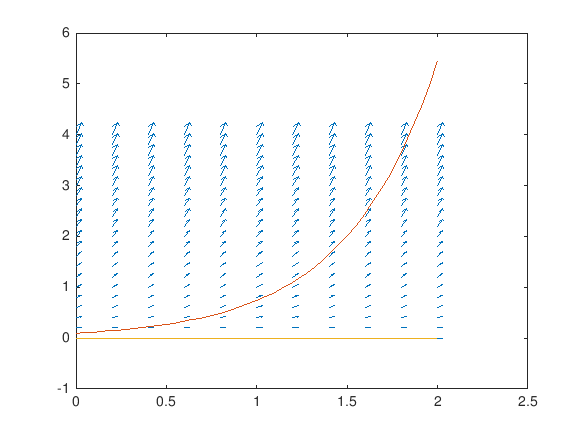

[t,y] = meshgrid(0:0.2:2,0:0.2:4);
u = ones(size(t));
v = f(t,y);

figure
quiver(t,y,u,v)
hold on
fplot(@(t)exp(2*t)/10, [0,2]),  %funcio que segueix el camp de direcció
fplot(@(t)zeros(size(t)), [0,2])

# Métodes de RK: ode23, ode45

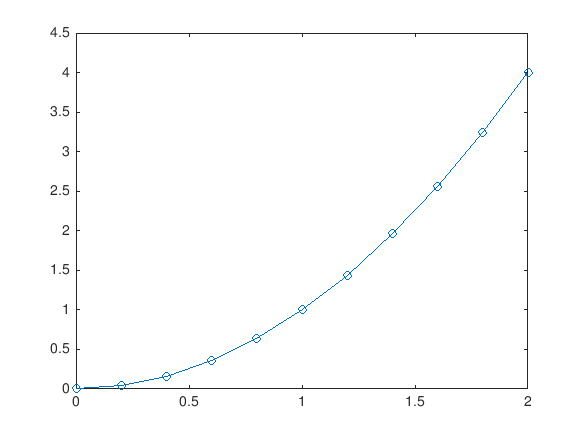

tspan = [0 2];
y0 = 0;
[t1,y1] = ode23(@(t,y) 2*t, tspan, y0);
plot(t1,y1, '-o')

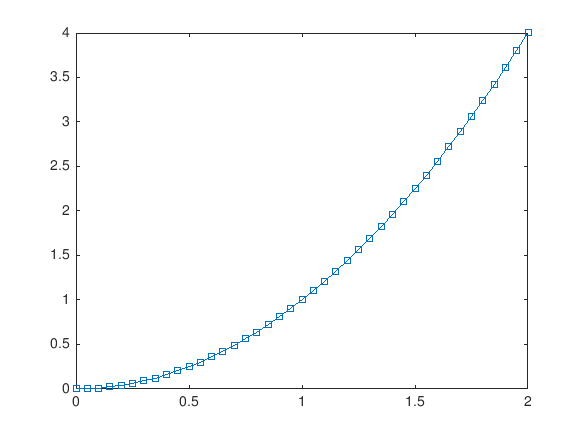

y0 = 0;
[t2,y2] = ode45(@(t,y) 2*t, tspan, y0);
plot(t2,y2, '-s')